a)取V0=1V；C=1μF；L=1μH，画出V（t）和I（t）随时间变化的图像

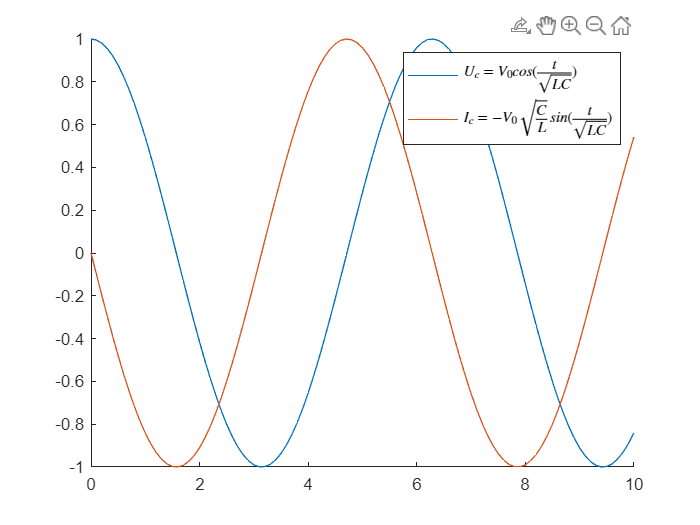

V0 = 1;
C = 1;
L = 1;

t = 0:0.1:10;
omega = 1/sqrt(L*C);
Uc = V0*cos(omega.*t);
Ic = -V0*sqrt(C/L)*sin(omega.*t);
hold on
g1 = plot(t, Uc, t, Ic);
legend(g1, '$U_c=V_0cos(\frac{t}{\sqrt{LC}})$', '$I_c=-V_0\sqrt{\frac{C}{L}}sin(\frac{t}{\sqrt{LC}})$', 'Interpreter', 'latex')

b)画出电容储能WE(t)和电感储能WH(t)的图像，并验证WE(t)+WI(t)=CV0^2/2

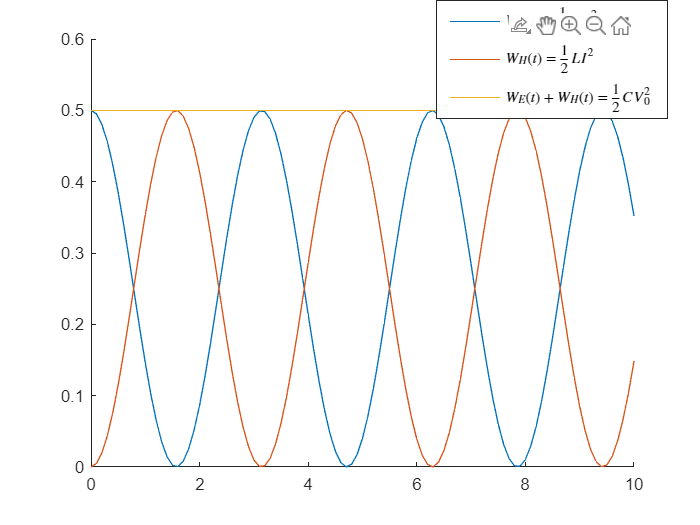

figure;
hold on
WE = 1/2*C.*Uc.^2;
WI = 1/2*L.*Ic.^2;
WW = WE + WI;
plot(t, WE)
plot(t, WI)
plot(t, WW)
legend('$W_E(t)=\frac{1}{2}CV^2$', '$W_H(t)=\frac{1}{2}LI^2$', '$W_E(t) + W_H(t)=\frac{1}{2}CV_0^2$', 'Interpreter', 'latex')
legend("Position",[0.67413,0.80933,0.22857,0.15357])